# **DSP HW5**

**By: 106061151 劉安得**

## **5.**

Hamming Windows


$$\begin{array}{l}
\mathrm{As}=53>50\\
\Delta \omega =\frac{6\ldotp 6\pi }{L}=0\ldotp 2\pi \\
L=33
\end{array}$$


M = 32

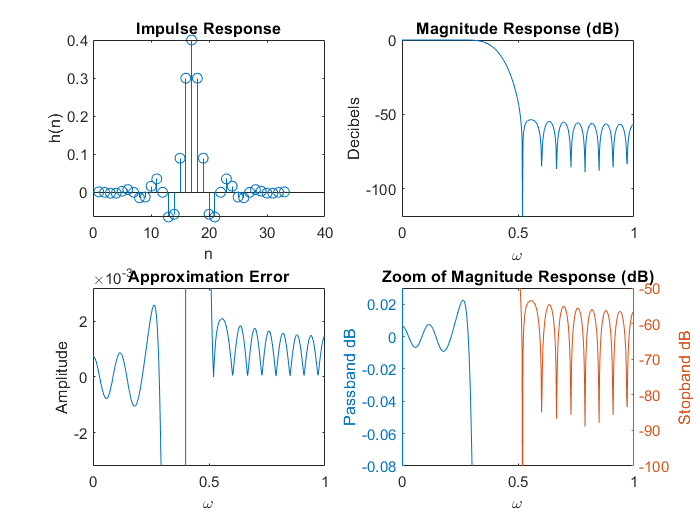

%Prob. 5
f = [0 0.4 0.4 1];
m = [1 1 0 0];
b = fir2(32, f, m);
[h, w] = freqz(b, 1);
hdb = mag2db(abs(h));
L = length(w);
LP = [ones(uint16(0.4*L), 1); zeros(L-uint16(0.4*L), 1)];
dh = abs(h)-LP;

figure
subplot(2, 2, 1)
stem(b)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
plot(w/pi, hdb)
title('Magnitude Response (dB)')
xlabel('\omega')
ylabel('Decibels')

subplot(2, 2, 3)
plot(w/pi, dh)
axis([0 1 -0.0032 0.0032])
title('Approximation Error')
xlabel('\omega')
ylabel('Amplitude')

subplot(2, 2, 4)
yyaxis left
plot(w/pi, hdb)
axis([0 1 -0.08 0.03])
title('Zoom of Magnitude Response (dB)')
xlabel('\omega')
ylabel('Passband dB')
yyaxis right
plot(w/pi, hdb)
axis([0 1 -100 -50])
ylabel('Stopband dB')

## 6.


$$\begin{array}{l}
\beta =0\ldotp 5842{\left(50-21\right)}^{0\ldotp 4} +0\ldotp 07886\left(50-21\right)=4\ldotp 53\\
M=\frac{A-8}{2\ldotp 285\Delta \omega }=\frac{50-8}{2\ldotp 285*0\ldotp 2\pi }=29\ldotp 25
\end{array}$$


M = 30

## 6. (a)

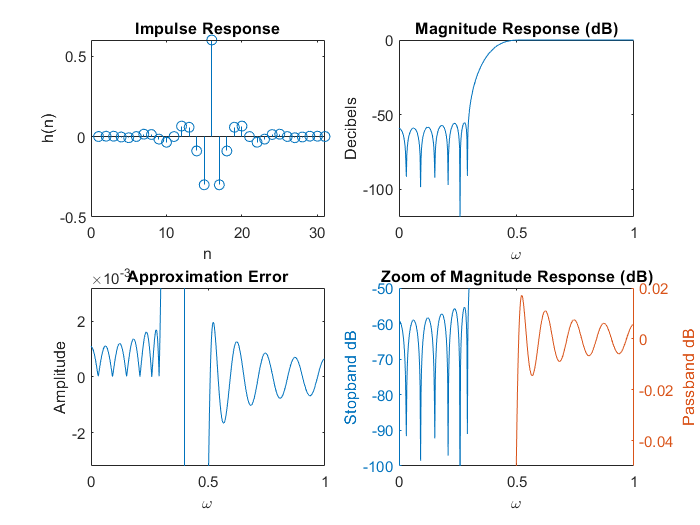

%Prob. 6(a)
f = [0 0.4 0.4 1];
m = [0 0 1 1];
M = 30;
b1 = fir2(M, f, m, kaiser(M+1,4.53));
[h1, w1] = freqz(b1, 1);
hdb1 = mag2db(abs(h1));
L = length(w1);
LP = [zeros(uint16(0.4*L), 1); ones(L-uint16(0.4*L), 1)];
dh1 = abs(h1)-LP;

figure
subplot(2, 2, 1)
stem(b1)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
plot(w1/pi, hdb1)
title('Magnitude Response (dB)')
xlabel('\omega')
ylabel('Decibels')

subplot(2, 2, 3)
plot(w1/pi, dh1)
axis([0 1 -0.0032 0.0032])
title('Approximation Error')
xlabel('\omega')
ylabel('Amplitude')

subplot(2, 2, 4)
yyaxis left
plot(w1/pi, hdb1)
axis([0 1 -100 -50])
title('Zoom of Magnitude Response (dB)')
xlabel('\omega')
ylabel('Stopband dB')
yyaxis right
plot(w1/pi, hdb1)
axis([0 1 -0.05 0.02])
ylabel('Passband dB')

## 6. (b)

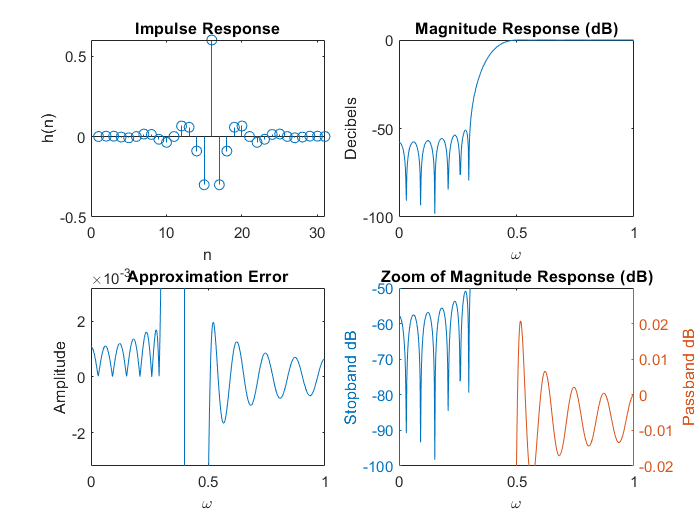

%Prob. 6(b)
b2 = fir1(M, 0.4, 'high', kaiser(M+1,4.53));
[h2, w2] = freqz(b2, 1);
hdb2 = mag2db(abs(h2));
dh2 = abs(h1)-LP;

figure
subplot(2, 2, 1)
stem(b2)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
plot(w2/pi, hdb2)
title('Magnitude Response (dB)')
xlabel('\omega')
ylabel('Decibels')

subplot(2, 2, 3)
plot(w2/pi, dh2)
axis([0 1 -0.0032 0.0032])
title('Approximation Error')
xlabel('\omega')
ylabel('Amplitude')

subplot(2, 2, 4)
yyaxis left
plot(w2/pi, hdb2)
axis([0 1 -100 -50])
title('Zoom of Magnitude Response (dB)')
xlabel('\omega')
ylabel('Stopband dB')
yyaxis right
plot(w2/pi, hdb2)
axis([0 1 -0.02 0.03])
ylabel('Passband dB')

## 7. (a)

%Prob. 7(a)
w = linspace(-2*pi, 2*pi, 512);
h1 = [1 2 3 -2 5 -2 3 2 1];
H1 = freqz(h1, 1, w);
Amp1 = H1./exp(-i*w*4);

figure
subplot(2, 2, 1)
stem(h1)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
zplane(h1, 1)
title('Pole-Zero Plots')

subplot(2, 2, 3)
plot(w, abs(H1))
title('Magnitude Response')
xlabel('\omega')
ylabel('|H(e^{i\omega})|')

subplot(2, 2, 4)
plot(w, Amp1)

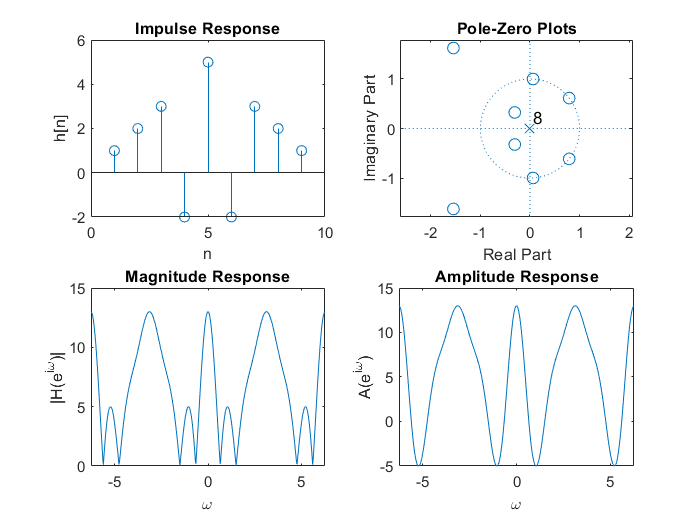

title('Amplitude Response')
xlabel('\omega')
ylabel('A(e^{i\omega})')

## 7. (b)

%Prob. 7(b)
h2 = [1 2 3 -2 -2 3 2 1];
H2 = freqz(h2, 1, w);
Amp2 = H2./exp(-i*w*7/2);

figure
subplot(2, 2, 1)
stem(h2)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
zplane(h2, 1)
title('Pole-Zero Plots')

subplot(2, 2, 3)
plot(w, abs(H2))
title('Magnitude Response')
xlabel('\omega')
ylabel('|H(e^{i\omega})|')

subplot(2, 2, 4)
plot(w, Amp2)

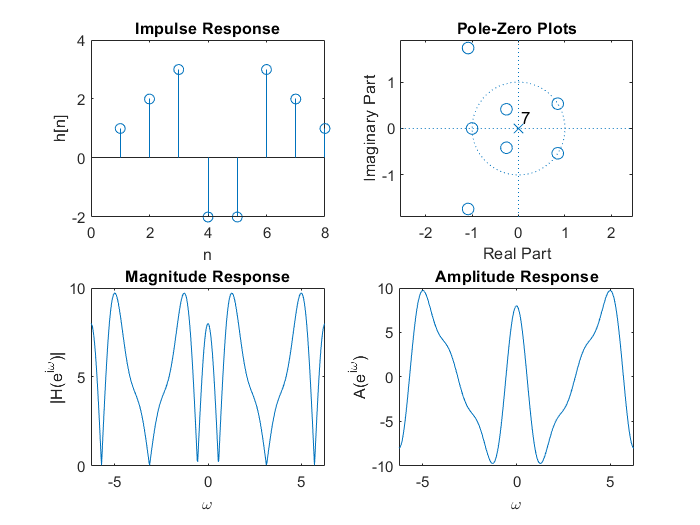

title('Amplitude Response')
xlabel('\omega')
ylabel('A(e^{i\omega})')

## 7. (c)

%Prob. 7(c)
h3 = [1 2 3 -2 0 2 -3 -2 -1];
H3 = freqz(h3, 1, w);
Amp3 = H3./exp(i*(pi/2-w*4));

figure
subplot(2, 2, 1)
stem(h3)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
zplane(h3, 1)
title('Pole-Zero Plots')

subplot(2, 2, 3)
plot(w, abs(H3))
title('Magnitude Response')
xlabel('\omega')
ylabel('|H(e^{i\omega})|')

subplot(2, 2, 4)
plot(w, Amp3)

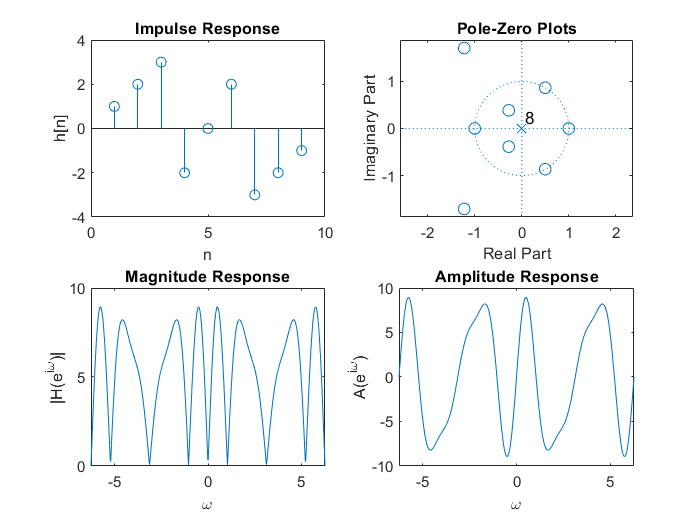

title('Amplitude Response')
xlabel('\omega')
ylabel('A(e^{i\omega})')

## 7. (d)

%Prob. 7(d)
h4 = [1 2 3 -2 2 -3 -2 -1];
H4 = freqz(h4, 1, w);
Amp4 = H4./exp(i*(pi/2-w*7/2));

figure
subplot(2, 2, 1)
stem(h4)
title('Impulse Response')
xlabel('n')
ylabel('h[n]')

subplot(2, 2, 2)
zplane(h4, 1)
title('Pole-Zero Plots')

subplot(2, 2, 3)
plot(w, abs(H4))
title('Magnitude Response')
xlabel('\omega')
ylabel('|H(e^{i\omega})|')

subplot(2, 2, 4)
plot(w, Amp4)

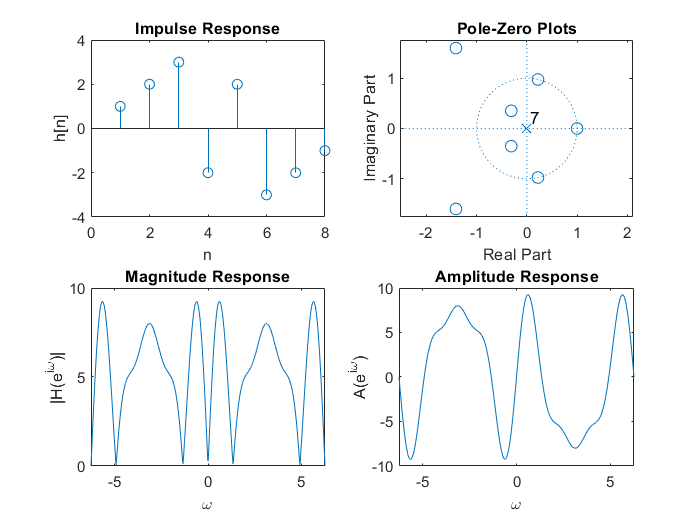

title('Amplitude Response')
xlabel('\omega')
ylabel('A(e^{i\omega})')

## 8. (a)

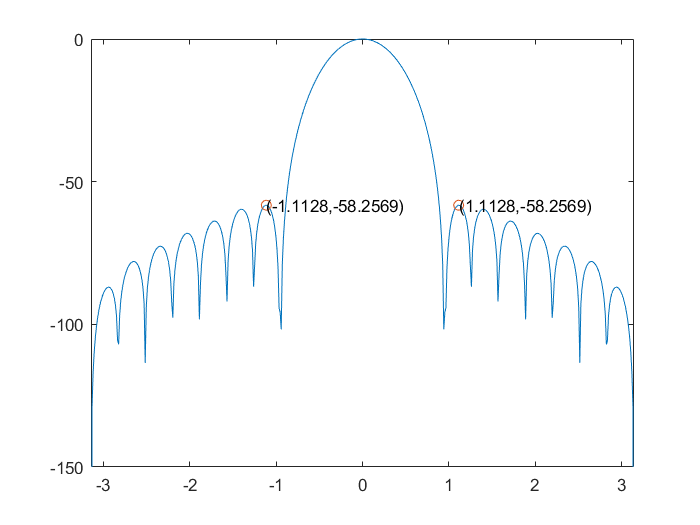

%Prob. 8(a)
w = linspace(-pi, pi, 512);
L1 = 21;
h1 = blackman(L1);
H1 = freqz(h1, 1, w);
Hdb1 = mag2db(abs(H1));
Hdb1_normalize = Hdb1 - max(Hdb1);
[pks1, locs1] = findpeaks(Hdb1_normalize,'SortStr','descend');
s1 = num2str(w(locs1(2)));
s2 = num2str(pks1(2));
s3 = num2str(w(locs1(3)));
s4 = num2str(pks1(3));

figure
plot(w, Hdb1_normalize, w(locs1(2:3)), pks1(2:3), 'o')
axis([-pi pi -150 0])
text(w(locs1(2)), pks1(2), strcat('(', s1, ',', s2, ')'))
text(w(locs1(3)), pks1(3), strcat('(', s3, ',', s4, ')'))

## 8. (b)

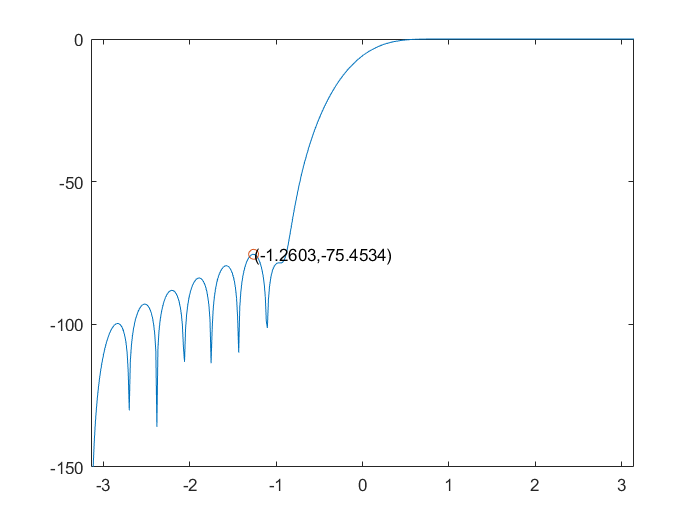

%Prob. 8(b)
Amp1 = H1./exp(-i*w*(L1-1)/2);
A1 = cumsum(Amp1);
Adb1 = mag2db(abs(A1));
Adb1_normalize = Adb1 - max(Adb1);
[pks2, locs2] = findpeaks(Adb1_normalize,'SortStr','descend');
idx1 = find(pks2 < -50);
s5 = num2str(w(locs2(idx1(1))));
s6 = num2str(pks2(idx1(1)));

figure
plot(w, Adb1_normalize, w(locs2(idx1(1))), pks2(idx1(1)), 'o')
axis([-pi pi -150 0])
text(w(locs2(idx1(1))), pks2(idx1(1)), strcat('(', s5, ',', s6, ')'))

## 8. (c)

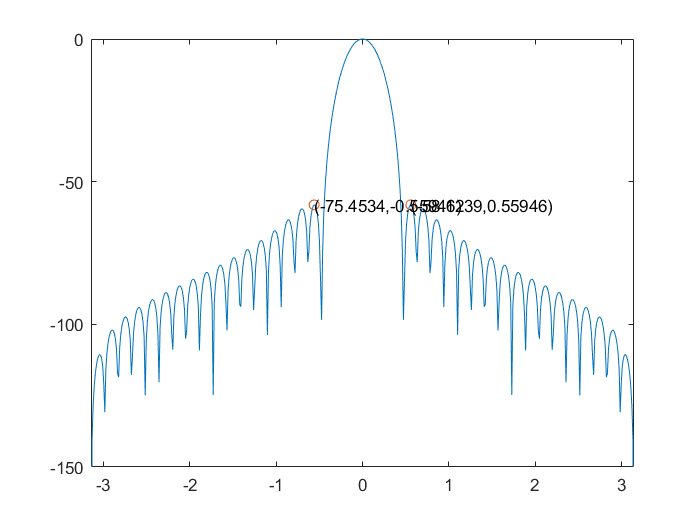

%Prob. 8(c)
L2 = 41;
h2 = blackman(L2);
H2 = freqz(h2, 1, w);
Hdb2 = mag2db(abs(H2));
Hdb2_normalize = Hdb2 - max(Hdb2);
[pks3, locs3] = findpeaks(Hdb2_normalize,'SortStr','descend');
s7 = num2str(w(locs3(2)));
s8 = num2str(pks3(2));
s9 = num2str(w(locs3(3)));
s10 = num2str(pks3(3));

figure
plot(w, Hdb2_normalize, w(locs3(2:3)), pks3(2:3), 'o')
axis([-pi pi -150 0])
text(w(locs3(2)), pks3(2), strcat('(', s6, ',', s7, ')'))
text(w(locs3(3)), pks3(3), strcat('(', s8, ',', s9, ')'))

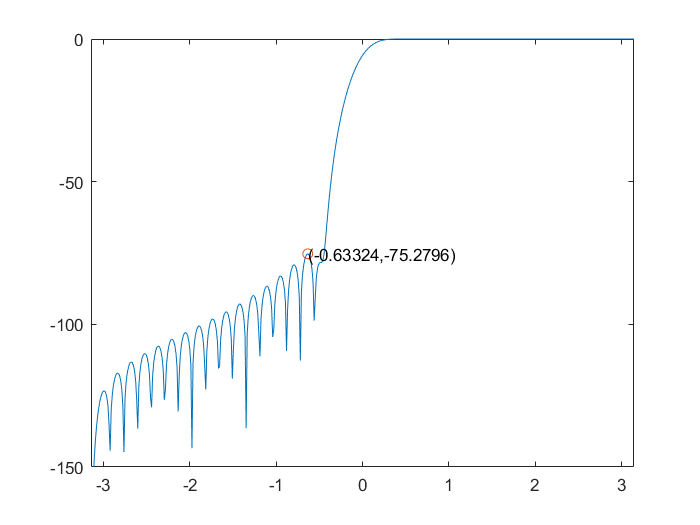


Amp2 = H2./exp(-i*w*(L2-1)/2);
A2 = cumsum(Amp2);
Adb2 = mag2db(abs(A2));
Adb2_normalize = Adb2 - max(Adb2);
[pks4,locs4] = findpeaks(Adb2_normalize,'SortStr','descend');
idx2 = find(pks4 < -50);
s11 = num2str(w(locs4(idx2(1))));
s12 = num2str(pks4(idx2(1)));

figure
plot(w, Adb2_normalize, w(locs4(idx2(1))), pks4(idx2(1)), 'o')
axis([-pi pi -150 0])
text(w(locs4(idx2(1))), pks4(idx2(1)), strcat('(', s11, ',', s12, ')'))

## 9. (a)(b)

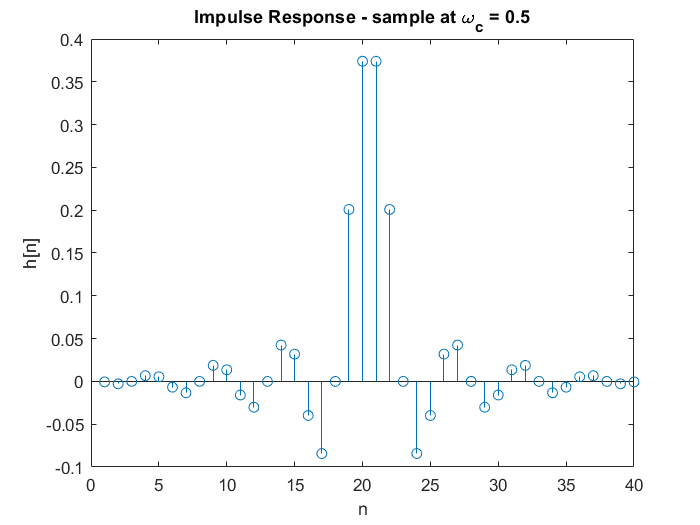

%Prob. 9(a)(b)
L = 40;
Ad1 = [ones(1, 8), 0.5, zeros(1, 23), 0.5, ones(1, 7)];
Psi1 = (L-1)/2*2*pi/L*[0:-1:-19, 20:-1:1];
Hd1 = Ad1.*exp(i*Psi1);
h1 = ifft(Hd1);
[H1, w1] = freqz(h1, 1);
Hdb1 = mag2db(abs(H1)); 
Lw1 = length(w1);

figure
stem(h1)
title('Impulse Response - sample at \omega_c = 0.5')
xlabel('n')
ylabel('h[n]')

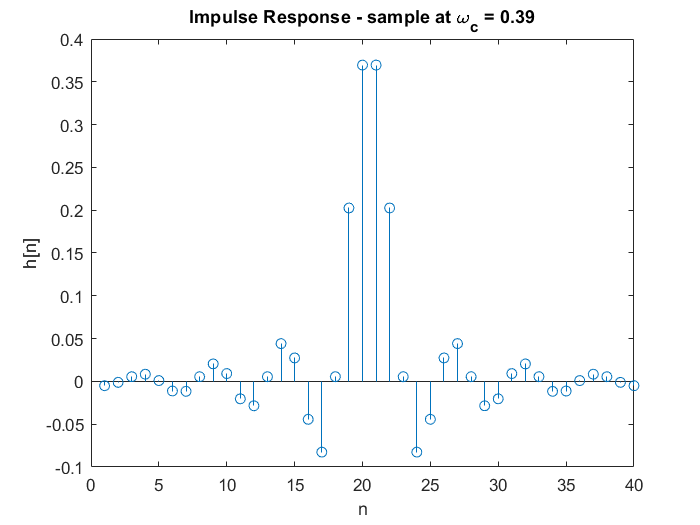


Ad2 = [ones(1, 8), 0.39, zeros(1, 23), 0.39, ones(1, 7)];
Psi2 = (L-1)/2*2*pi/L*[0:-1:-19, 20:-1:1];
Hd2 = Ad2.*exp(i*Psi2);
h2 = ifft(Hd2);
[H2, w2] = freqz(h2, 1);
Hdb2 = mag2db(abs(H2)); 
Lw2 = length(w2);

figure
stem(h2)
title('Impulse Response - sample at \omega_c = 0.39')
xlabel('n')
ylabel('h[n]')


figure
hold on
plot(w1/pi, Hdb1, 'r')
plot(w2/pi, Hdb2, 'g')
hold off
axis([0 1 -100 0])
legend('sample at \omega_c = 0.5','sample at \omega_c = 0.39')

Asd1 = max(Hdb1(uint16(0.45*Lw1): Lw1-1))

Asd1 = -29.7041

Asd2 = max(Hdb2(uint16(0.45*Lw2): Lw2-1))

Asd2 = -42.2066

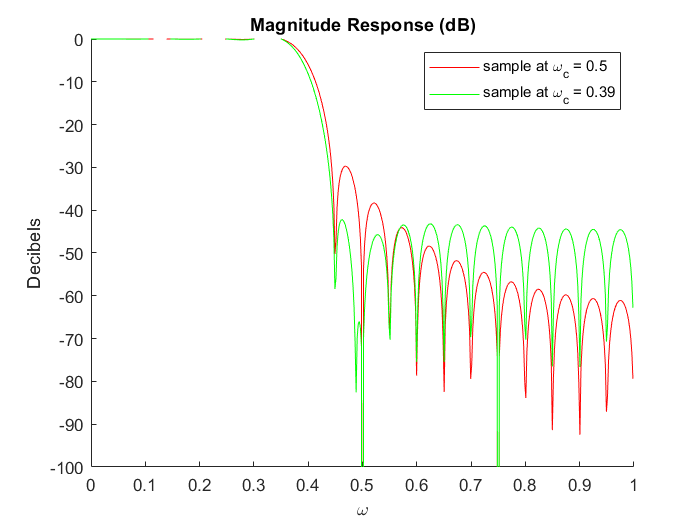

title('Magnitude Response (dB)')
xlabel('\omega')
ylabel('Decibels')

## 9. (c)

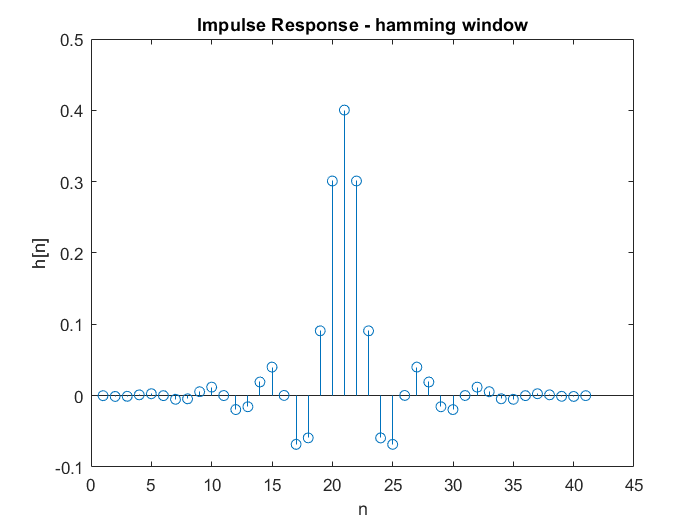

%Prob. 9(c)
f = [0 0.4 0.4 1];
m = [1 1 0 0];
h3 = fir2(40, f, m);
[H3, w3] = freqz(h3, 1);
Hdb3 = mag2db(abs(H3));
Lw3 = length(w3);

figure
stem(h3)
title('Impulse Response - hamming window')
xlabel('n')
ylabel('h[n]')

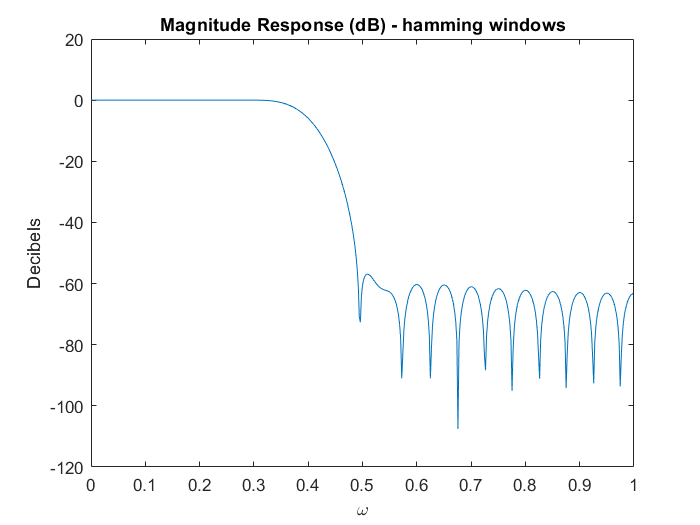


figure
plot(w3/pi, Hdb3)
title('Magnitude Response (dB) - hamming windows')
xlabel('\omega')
ylabel('Decibels')


Asd3 = max(Hdb3(uint16(0.5*Lw3): Lw3-1))

Asd3 = -56.9291

hamming window 表現還是比較好，frequency-sampling method 比較適合用在非 LP, HP, BP, BS 的時機